## **Laboratorio 03**

Esta es una prueba

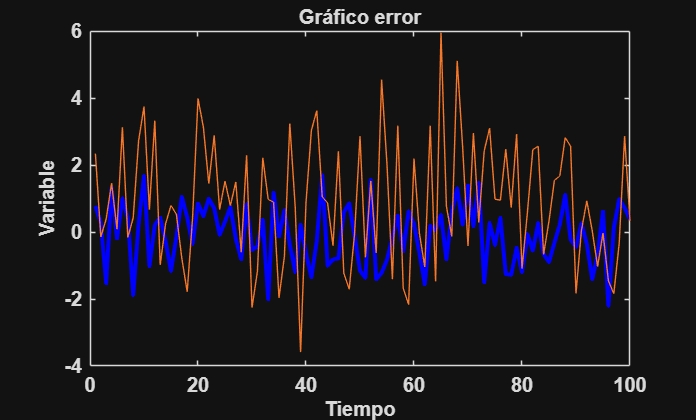

%% Clase 3

clear; % Limpia memoria

close all; % cierra ventanaas

% ST = Tendencia + ciclos + error

% Define the components of the model

trend = 1:100; % trend component
error1 = randn(1,100);
error2 = 1 + 2*randn(1,100);

% cycles = sin(linspace(0, 2*pi, 10)); % Example cyclic component
% error = randn(1, 10); % Example error component

figure
plot(trend, error1, "blue", "LineWidth" , 2);
line(trend, error2);
title("Gráfico error", "FontSize", 10);
xlabel("Tiempo", "FontSize", 10);
ylabel("Variable", "FontSize", 10);
set(gca, 'FontWeight', "bold");

Ahora haremos otra prueba

x = 1:20;
x

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


#### Generando gráficos

figure
plot(trend, error1, "blue", "LineWidth" , 2);
line(trend, error2);
title("Gráfico error", "FontSize", 10);
xlabel("Tiempo", "FontSize", 10);
ylabel("Variable", "FontSize", 10);
set(gca, 'FontWeight', "bold");

### Tendencia

a_pend =0.07;

tendencia = 10 + a_pend*trend;

serie_tiempo = error2 + tendencia;

figure
subplot(2,2,1)
plot(trend, error2);
title("Error");
subplot(2,2,2)
plot(trend, tendencia);
title("Tendencia");
subplot(2,2,3)
plot(trend, serie_tiempo);
title("Serie de Tiempo")

### Ciclos

Repeticiones a corto o largo plazo

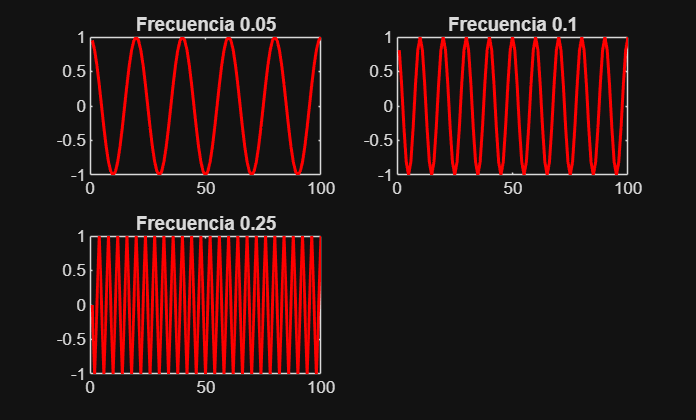

Amplitud = 1;

Frecuencias = [5/100, 1/10, 5/20];


for i = 1:length(Frecuencias)
    ciclo = Amplitud * cos(2*pi*Frecuencias(i)*trend);
    subplot(2,2,i)
    plot(trend, ciclo, 'r', 'LineWidth', 1.5); % Plot the cycle component
    title("Frecuencia " + Frecuencias(i))
end

Completo

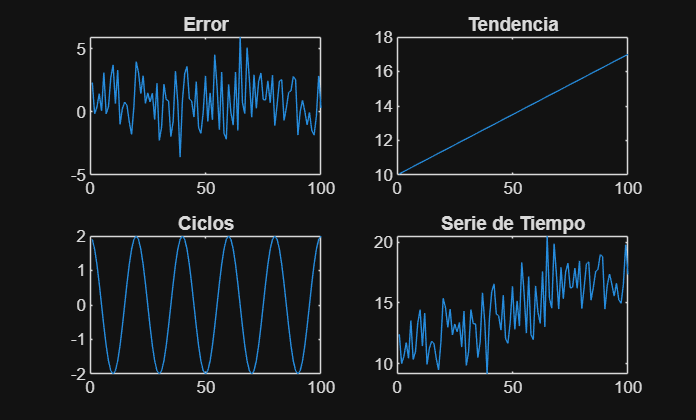

Amplitud = 2;
Frecuencia = Frecuencias(1);

ciclos = Amplitud * cos(2*pi*Frecuencia*trend);


figure
subplot(2,2,1)
plot(trend, error2);
title("Error");
subplot(2,2,2)
plot(trend, tendencia);
title("Tendencia");
subplot(2,2,3)
plot(trend, ciclos);
title("Ciclos");
subplot(2,2,4)
plot(trend, serie_tiempo);
title("Serie de Tiempo")